# Traccia 2: Manipolatore a 2 DoF

### Manipolatore a 2 DoF planare con attuatori elastici in serie (SEA)

TODO: Un video dove il braccio raggiunge una serie di punti aleatorie

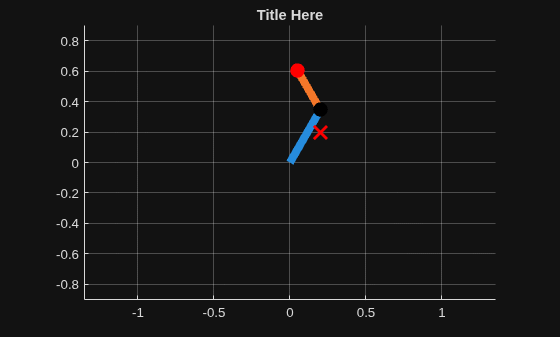

*Figura 1: Manipolatore planare *$2R$* con Series Elastic Actuators (SEA). I dischi ai giunti rappresentano i motori *$(M_1 , M_2)$* con coordinate [*$\theta_1$*, *$\theta_2$]*. Le molle angolari di rigidezza [*$k_1$*, *$k_2$]* collegano elasticamente in serie i rotori dei motori ai link corrispondenti, con coordinate articolari [*$q_1$*, *$q_2$]* .*

### Splorando la Dinamica del Sistema

Dato la dinamica dei link e dei motiri, rispettivamente:

$M (q) \ddot{q} + C(q, \dot{q}) \dot{q} + G(q) = Ks (\theta - q)$           *(link)*

$J_m \ddot{\theta} + B_m \dot{\theta} = \tau - K_s (\theta - q)$                           * (motori)*

Giociamo un po' con i dati modelli dinamici, per calibrarsi nel problema e rassicurarsi che gli abbiamo fatti bene.  

TODO: grafo interattivo mostrando i vettori di forza, inerzia, coppia 

### Dinamica del Sistema

Le equazioni del moto si suddividono in due sottosistemi accoppiati tramite la coppia elastica dei SEA. 

dove 

- $\tau = [\tau_1, \tau_2 ]^\top$ è il vettore delle coppie ai motori (ingressi di controllo)

- $K_s = diag[k_1 , k_2]$ è la matrice di rigidezza

- $J_m = diag[Jm_1 , Jm_2]$ inerzia

- $B_m = diag[Bm_1 , Bm_2]$ smorzamento dei motori.

### Parametri

% refresh MAT file
config
model = Model(init);

% inv(model.J_m)*([0;0] - model.K_s(q_0 - q_0) - model.B_m*dtheta_0)

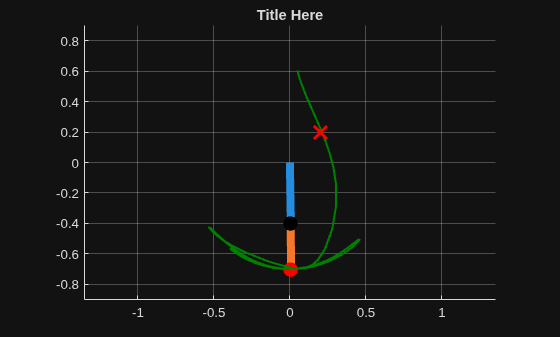

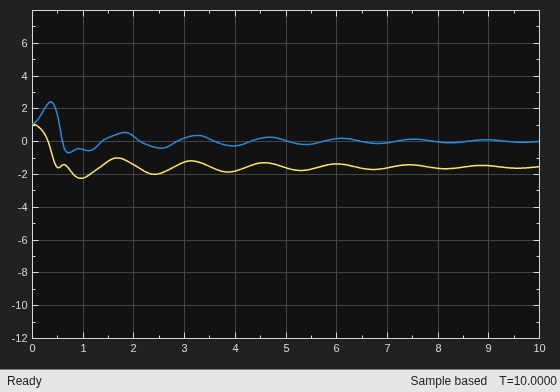

model.targetQ([.2,.2])